#### Laser Power Calibration - May 24 2024

% Housekeeping

close all;
clc;
clear;
format long;

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/";
file_name = "Laser Power Calibration.xlsx";
file_path = strcat(data_path,file_name);
data1 = readmatrix(file_path);

power = data1(:,1);
source = data1(:,6);
source_err = data1(:,7);
objective = data1(:,8);
objective_err = data1(:,9);

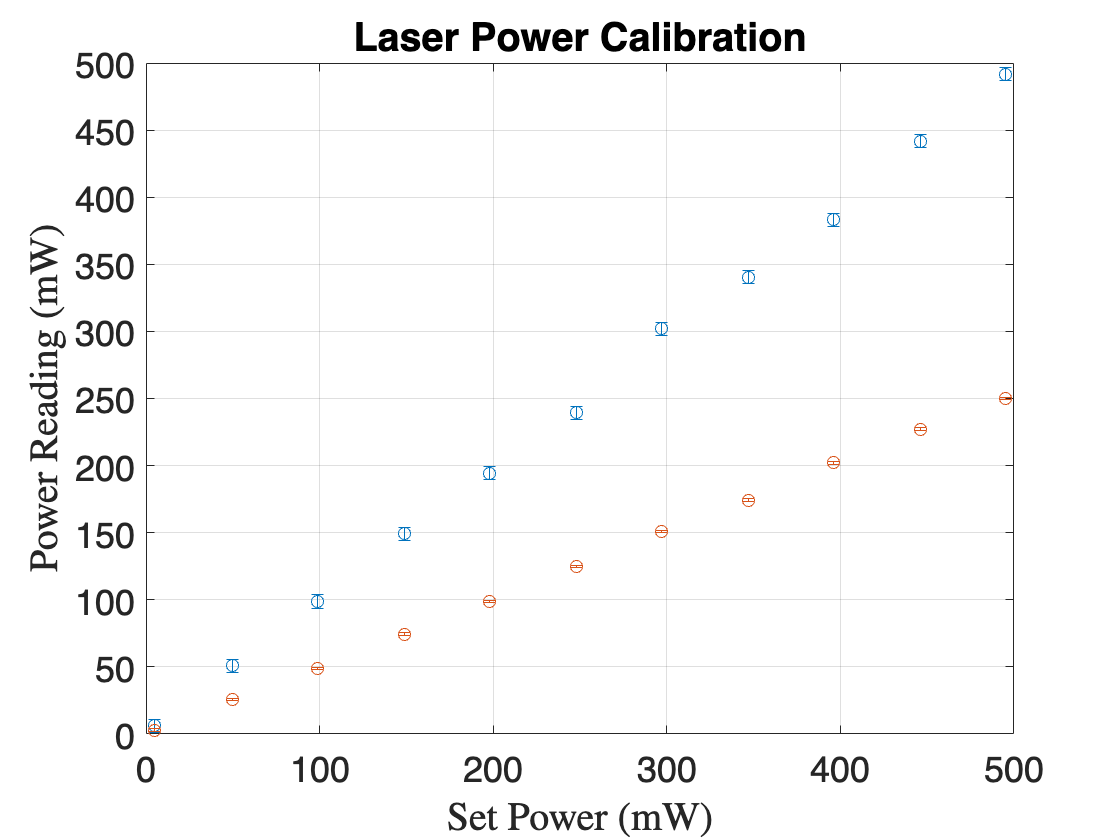

% Plotting initial calibration data

fig1 = figure;
ax1 = axes(fig1);
hold on
grid on

errorbar(ax1, power, source, source_err, source_err, "o");
ax1.FontSize = 12;
ax1.Box = "on";
xlabel(ax1, "Set Power (mW)", 'Interpreter', 'latex');
ylabel(ax1, "Power Reading (mW)", 'Interpreter', 'latex');
title("Laser Power Calibration")
ax1.FontSize = 18;
hold on;
errorbar(ax1, power, objective, objective_err, objective_err, "o");

% Fitting data with trendlines

ft = fittype('a*x + b');
[f, gof, fit_output] = fit(power, source, ft, 'Weights', source_err.^(-2), 'StartPoint', [1, 0])

f =      General model:
     f(x) = a*x + b
     Coefficients (with 95% confidence bounds):
       a =      0.9843  (0.9642, 1.004)
       b =      0.8994  (-4.983, 6.782)

gof = struct with fields:
           sse: 7.572020856909078
       rsquare: 0.999268965005190
           dfe: 9
    adjrsquare: 0.999187738894656
          rmse: 0.917243506800498


fit_output = struct with fields:
             numobs: 11
           numparam: 2
          residuals: [11×1 double]
           Jacobian: [11×2 double]
           exitflag: 2
      firstorderopt: 1.836691664314216e-06
         iterations: 5
          funcCount: 18
       cgiterations: 0
          algorithm: 'trust-region-reflective'
           stepsize: 2.511726467651140e-07
            message: 'Success, but fitting stopped because change in coefficients less than tolerance (TolX).'
       bestfeasible: []
    constrviolation: []


% plot the fit function with its estimated parameters 
% use a linespace to get your x-values 

x = linspace(0, 500, 1000);
y = f.a*x + f.b;
plot(ax1, x, y,'b-', 'LineWidth', 1.5);
ax1.XLim = [0 500];

[f1, gof1, fit_output1] = fit(power, objective, ft, 'Weights', objective_err.^(-2), 'StartPoint', [0.5, 0])

f1 =      General model:
     f1(x) = a*x + b
     Coefficients (with 95% confidence bounds):
       a =      0.5079  (0.503, 0.5129)
       b =      -0.636  (-2.079, 0.8068)

gof1 = struct with fields:
           sse: 11.386410996158638
       rsquare: 0.999834787688001
           dfe: 9
    adjrsquare: 0.999816430764445
          rmse: 1.124791881794565


fit_output1 = struct with fields:
             numobs: 11
           numparam: 2
          residuals: [11×1 double]
           Jacobian: [11×2 double]
           exitflag: 1
      firstorderopt: 6.217248937900877e-12
         iterations: 1
          funcCount: 6
       cgiterations: 0
          algorithm: 'trust-region-reflective'
           stepsize: 0.636057586896920
            message: 'Success. Fitting converged to a solution.'
       bestfeasible: []
    constrviolation: []


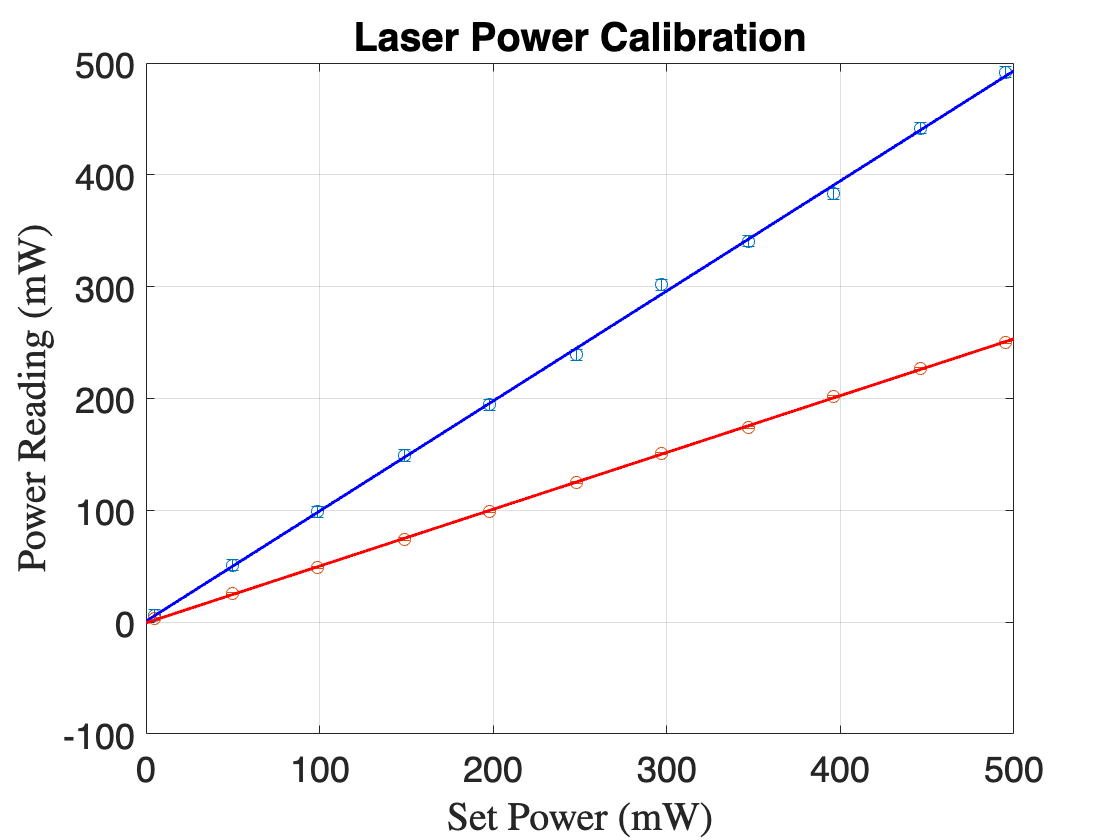

% plot the fit function with its estimated parameters 
% use a linespace to get your x-values 

x1 = linspace(0, 500, 1000);
y1 = f1.a*x + f1.b;
plot(ax1, x1, y1,'r-', 'LineWidth', 1.5);
ax1.XLim = [0 500];

% Performing goodness of fit calculations

% Source fit goodness

min_chi2 = gof.sse;
ndof = gof.dfe;
p_value = chi2cdf(min_chi2, ndof, 'upper')

p_value =    0.577782944035913


reduced_chi2 = min_chi2/ndof

reduced_chi2 =    0.841335650767675


% Objective fit goodness

min_chi2 = gof1.sse;
ndof = gof1.dfe;
p_value = chi2cdf(min_chi2, ndof, 'upper')

p_value =    0.250149192655205


reduced_chi2 = min_chi2/ndof

reduced_chi2 =    1.265156777350960
